robot = {};
robot.X = 50;
robot.Y = 60;
robot.deltaX = 1;
robot.deltaY = 1;

map = zeros(100, 100);

% x1 y1; x2 y2
square = [40, 30; 60, 70]

square =     40    30
    60    70



map(square(1,2):square(2,2), square(1,1)) = 1;
map(square(1,2), square(1,1):square(2,1)) = 1;
map(square(1,2):square(2,2), square(2,1)) = 1;
map(square(2,2), square(1,1):square(2,1)) = 1;

robot.Map = map;
boundary = getBoundary(robot.Map, robot.X, robot.Y)

boundary =     70    50
    70    51
    70    52
    70    53
    70    54
    70    55
    70    56
    70    57
    70    58
    70    59


boundaryDist = boundaryWithDistance(boundary, robot.X, robot.Y)

ans = 117

boundaryDist =    70.0000   50.0000   10.0000
   70.0000   51.0000   10.0499
   70.0000   52.0000   10.1980
   70.0000   53.0000   10.4403
   70.0000   54.0000   10.7703
   70.0000   55.0000   11.1803
   70.0000   56.0000   11.6619
   70.0000   57.0000   12.2066
   70.0000   58.0000   12.8062
   70.0000   59.0000   13.4536



closest = closestUnexplored(boundary, robot.X, robot.Y)

closest =     50    70


closest =     50    70


closestVel = closestUnexploredWithVelocity(boundary, robot.X, robot.Y, robot.deltaX, robot.deltaY)

closest =     50    70


closest =     51    70


closest =     52    70


closest =     53    70


closest =     54    70


closest =     55    70


closest =     56    70


closest =     57    70


closest =     58    70


closest =     59    70


closestVel =     59    70



robotMap = binaryOccupancyMap(map);

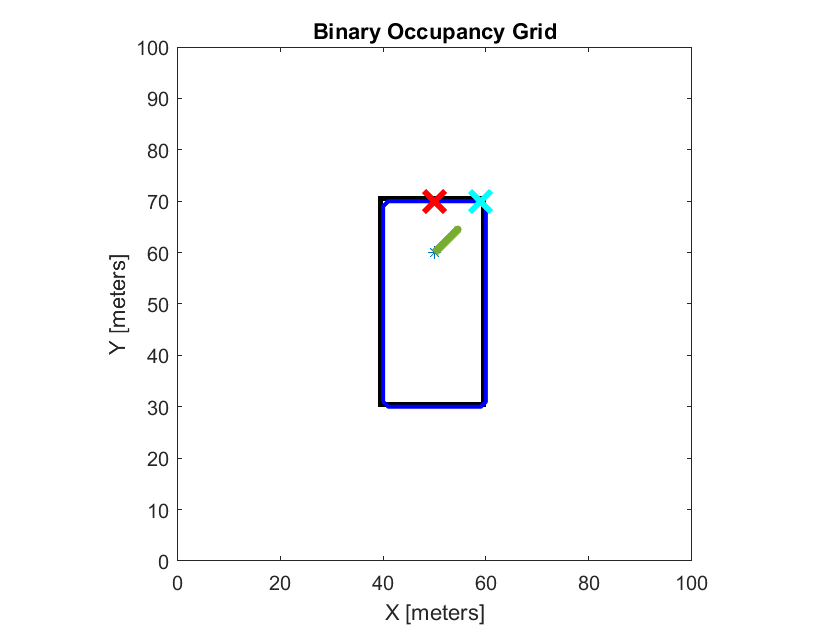

arrowMult = 5;

show(robotMap)
hold on
plot(robot.X, robot.Y, "*")
plot(boundary(:,2), boundary(:,1), "blue", "LineWidth",2)
plot(closest(1), closest(2), "x","color","red", "MarkerSize", 15, "LineWidth",3)
plot(closestVel(1), closestVel(2), "x","color","cyan", "MarkerSize", 15, "LineWidth",3)
quiver(robot.X, robot.Y, robot.deltaX * arrowMult, robot.deltaY * arrowMult, "LineWidth",4)
hold off

function boundary = getBoundary(robotMap, robotX, robotY)
    pixel = robotY;
    visible = robotMap(robotY, robotX);
    for i = robotY:robotY+100
        if robotMap(i, robotX) ~= visible
            pixel = i;
            break;
        end
    end
    boundary = bwtraceboundary(robotMap, [pixel, robotX], 'N');
end

function closest = closestUnexplored(boundary, robotX, robotY)
    closest = [0, 0];
    closestDistance = 100000;
    for i = 1:size(boundary, 1)
        newDist = distance([robotY, robotX], boundary(i,:));
        if newDist < closestDistance
            closestDistance = newDist;
            closest = [boundary(i,2), boundary(i,1)]
        end
    end
end

function boundaryDist = boundaryWithDistance(boundary, robotX, robotY)
    boundaryDist = boundary;
    size(boundary, 1)
    for i = 1:size(boundary, 1)
        boundaryDist(i,3) = distance([robotY, robotX], boundary(i,:));
    end
end

function closest = closestUnexploredWithVelocity(boundary, robotX, robotY, deltaX, deltaY)
    closest = [0, 0];
    closestDistance = 100000;
    for i = 1:size(boundary, 1)
        deltaRobot = [deltaX, deltaY];
        normRobot = deltaRobot / norm(deltaRobot);
        
        pointDelta = [boundary(i,2)-robotX, boundary(i,1)-robotY];
        normPoint = pointDelta / norm(pointDelta);
        
        dist = distance([robotY, robotX], boundary(i,:));
        
        newDist = distanceVelocityHeuristic(dist, normRobot, normPoint);
        
        if newDist < closestDistance
            closestDistance = newDist;
            closest = [boundary(i,2), boundary(i,1)]
        end
    end
end

function heuristic = distanceVelocityHeuristic(dist, normRobot, normPoint)
    velocityCoeff = 10;
    diffX = abs(normRobot(1) - normPoint(1));
    diffY = abs(normRobot(2) - normPoint(2));
    heuristic = dist + diffX * velocityCoeff + diffY * velocityCoeff;
end

function dist = distance(a, b)
    dist = sqrt((a(1) - b(1)) ^ 2 + (a(2) - b(2)) ^ 2);
end